# National Debt

## 1.

Load `natdebt.mat`.  This file contains a record of the U.S. national debt from 1950 – 2000, and also from 2000 – 2010.

load natdebt

## 2.

Plot the time-series of the debt for 1950 – 2000 (stored in the variables `debt20` and `yr20`).

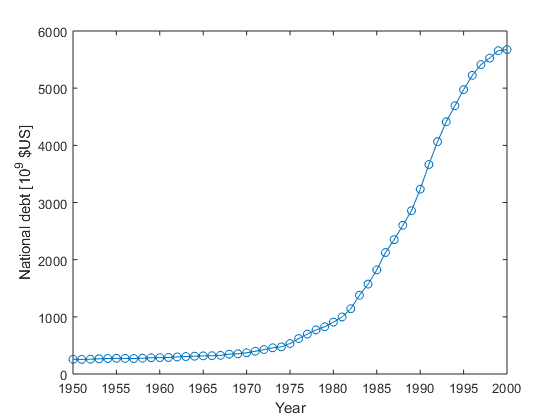

plot(yr20,debt20,'o-')
xlabel('Year')
ylabel('National debt [10^9 $US]')

## 3.

Note that the plot appears to follow a *logistic* (sigmoid) curve.  A possible model, then, would be


$$y = y_0+\frac{L}{1+e^{-k(x-x_0)}}$$


Estimate the parameters `y0` using `y0 = min(y)` and `L` using `L = max(y) - min(y)`.

y0=min(debt20)

y0 = 255.2220

L = max(debt20)-min(debt20)

L = 5.4190e+03

## 4.

To prevent ill conditioning, transform `yr20` using the `rescale` function.

The model above can be manipulated algebraically to obtain $z = -k(x-x_0)$ where


$$z = \ln\left(\frac{L}{y-y_0} - 1\right)$$


Use this transformation to calculate `z` from `debt20`.  Because of how `L` and `y0` has been estimated, `z` will contain infinite values. Replace these with `NaN`s.

x = (yr20-1950)/50;
z = log(L./(debt20 -y0) - 1);
z(~isfinite(z)) = NaN;

## 5.

Plot `z` as a function of `x`.  Perform a linear regression to obtain estimates for k and x0.

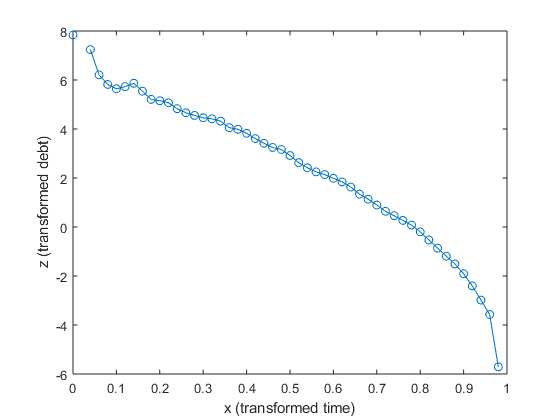

plot(x,z,'o-')
xlabel('x (transformed time)')
ylabel('z (transformed debt)')

transfit = fitlm(x,z,'linear')

transfit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________
    (Intercept)     7.5473     0.19801     38.115    5.3467e-37
    x1             -10.219      0.3447    -29.647    4.5088e-32

Number of observations: 49, Error degrees of freedom: 47
Root Mean Squared Error: 0.684
R-squared: 0.949,  Adjusted R-Squared 0.948
F-statistic vs. constant model: 879, p-value = 4.51e-32

%  Get the coefficients
b = transfit.Coefficients.Estimate;
k = -b(2)

k = 10.2194

x0 = b(1)/k

x0 = 0.7385

## 6.

Perform a full nonlinear regression on the original model, using the estimated parameters as starting guesses.

b = [y0;L;k;x0];
f = @(b,x) b(1) + b(2)./(1+exp(-b(3)*(x-b(4))));
%  Do nonliner fit to get parameters
nonlin = fitnlm(x,debt20,f,b)

nonlin = Nonlinear regression model:
    y ~ b1 + b2/(1 + exp( - b3*(x - b4)))

Estimated Coefficients:
          Estimate       SE        tStat       pValue  
          ________    _________    ______    __________
    b1     291.86        11.538    25.295    5.0862e-29
    b2     6147.3        75.775    81.126    3.5994e-52
    b3     11.054       0.21777    50.761    1.0405e-42
    b4    0.80111     0.0027955    286.57    7.2855e-78

Number of observations: 51, Error degrees of freedom: 47
Root Mean Squared Error: 53
R-Squared: 0.999,  Adjusted R-Squared 0.999
F-statistic vs. constant model: 1.99e+04, p-value = 6.45e-73

## 7.

Plot the resulting model and the actual data on the same set of axes.

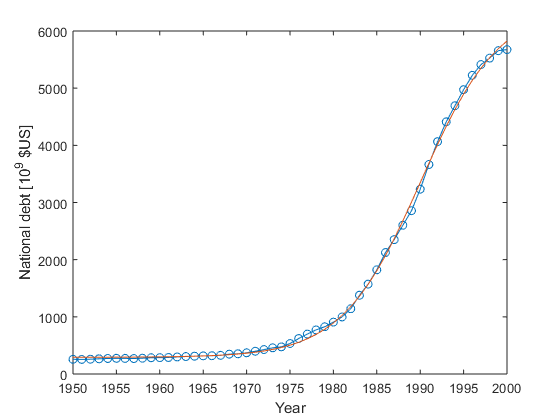

predd20 = predict(nonlin,x);  % or evaluate function handle: predd20 = f(b,x);
plot(yr20,debt20,'o-',yr20,predd20)
xlabel('Year')
ylabel('National debt [10^9 $US]')

## 8.

The variables `debt21` and `yr21` contain data for 2000 – 2010.  Add the model’s predictions for these years to your plot.

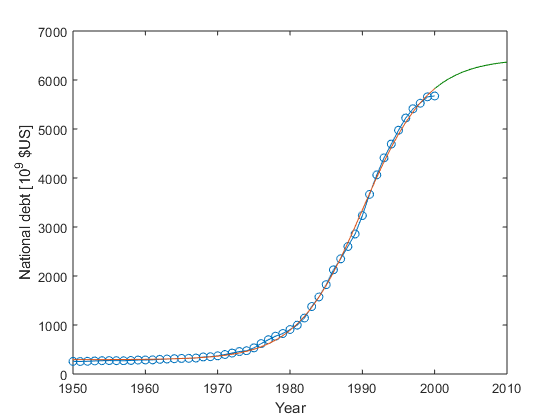

xnew = (yr21-1950)/50;
%  Add model prediction to graph
predd21 = predict(nonlin,xnew);  % or evaluate function handle: predd20 = f(b,xnew);
hold on
plot(yr21,predd21,'Color',[0 0.5 0])

## 9.

Add the actual data values.  (Moral: Extrapolation is dangerous!)

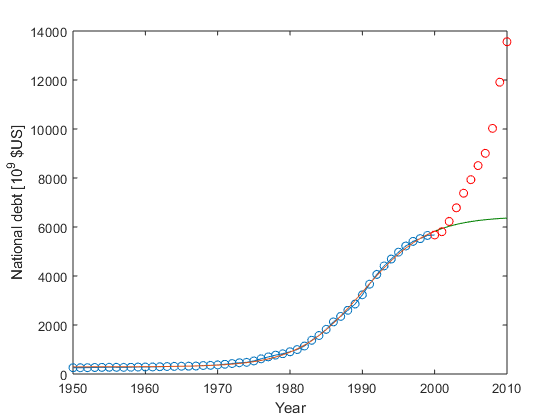

plot(yr21,debt21,'ro')
%  I was way off!
hold off